# Taller 3

# Gabriela María Castro Beltrán

# Consensus-Based Optimization

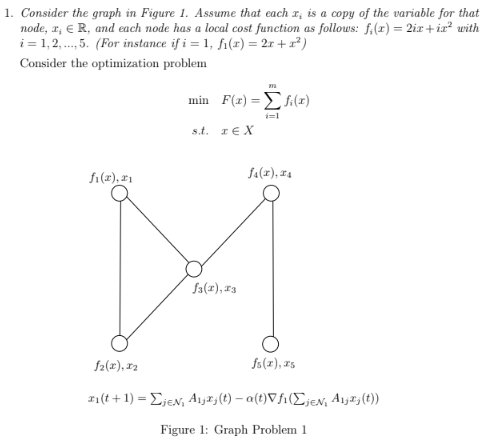

Este taller explora la optimización basada en consenso a través de diferentes enfoques de cálculo del consenso en una red de nodos interconectados. Se implementaron dos métodos principales: el consenso basado en los vecinos directos y el consenso utilizando la matriz laplaciana. Ambos enfoques fueron aplicados en distintos ejercicios para observar sus diferencias y efectividad en la convergencia de los estados de los nodos.

## **Primer Método: Consenso por Vecinos Directos**

En este método, se define una red de **n = 5** nodos con una matriz de adyacencia  que representa las conexiones entre ellos. La matriz de adyacencia se normaliza para ser doblemente estocástica, asegurando que la suma de sus filas sea 1. Luego, se inicializan los estados de los nodos con valores aleatorios.

Cada nodo actualiza su estado en cada iteración con un promedio ponderado de los estados de sus vecinos y un término de gradiente para minimizar una función de costo local . Finalmente, el consenso es estimado como el promedio de los estados finales de los nodos. Se grafican las trayectorias de los estados de los nodos a lo largo del tiempo.

% Parámetros iniciales
n = 5; % Número de nodos
alpha = 0.01; % Tasa de aprendizaje (ajustar según sea necesario)
max_iter = 100; % Número máximo de iteraciones
x = zeros(n, max_iter); % Inicializar estados de los nodos
x_a(:, 1) = rand(n, 1) % Valores iniciales aleatorios para los estados

x_a =     0.6901
    0.8537
    0.4679
    0.4585
    0.8061



% Matriz de adyacencia (grafo en la Figura 1)
A = [0 1 1 0 0;
     1 0 1 0 0;
     1 1 0 1 0;
     0 0 1 0 1;
     0 0 0 1 0];

% Normalizar la matriz de adyacencia para que sea doblemente estocástica
A = A ./ sum(A, 2)

A =          0    0.5000    0.5000         0         0
    0.5000         0    0.5000         0         0
    0.3333    0.3333         0    0.3333         0
         0         0    0.5000         0    0.5000
         0         0         0    1.0000         0



% Algoritmo de consenso distribuido
for t = 1:max_iter-1
    for i = 1:n
        % Obtener los vecinos del nodo i
        neighbors = find(A(i, :) > 0);
        
        % Calcular el promedio ponderado de los estados de los vecinos
        weighted_sum = sum(A(i, neighbors) .* x_a(neighbors, t)');
        
        % Calcular el gradiente de la función de costo local
        gradient = 2*i + 2*i * x_a(i, t);
        
        % Actualizar el estado del nodo i
        x_a(i, t+1) = weighted_sum - alpha * gradient;
    end
end

% Valor de consenso (estado final de los nodos)
consensus_value = mean(x_a(:, end)); % Promedio de los estados finales de todos los nodos
disp('El valor de consenso es:');

El valor de consenso es:


disp(consensus_value);

   -0.9932
   -0.9933
   -0.9936
   -0.9941
   -0.9945



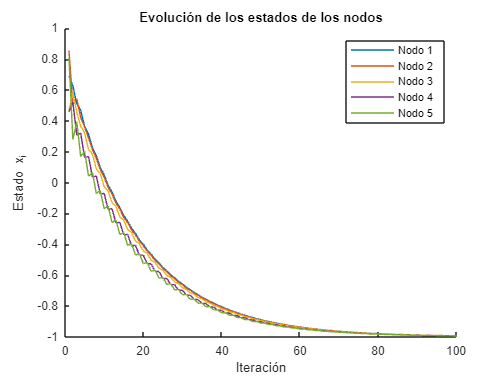


% Graficar
figure;
hold on;
for i = 1:n
    plot(1:max_iter, x_a(i, :), 'DisplayName', ['Nodo ' num2str(i)]);
end
xlabel('Iteración');
ylabel('Estado x_i');
legend show;
title('Evolución de los estados de los nodos');
hold off;

## **Segundo Método: Consenso con la Matriz Laplaciana**

En este enfoque, se define la misma red de **n = 5** nodos y se construye la matriz laplaciana L=D-A , donde D es la matriz de grado. Se calcula la matriz de consenso  con el ajuste de lambda=-1/n.

Cada nodo actualiza su estado utilizando  W(t) y el término de gradiente correspondiente en cada iteración. Al final del proceso, se calcula el valor de consenso promedio y se visualiza la evolución de los estados de los nodos en un gráfico.

% Matriz de adyacencia (grafo en la Figura 1)
A = [0 1 1 0 0;
     1 0 1 0 0;
     1 1 0 1 0;
     0 0 1 0 1;
     0 0 0 1 0];

% Normalizar la matriz de adyacencia para que sea doblemente estocástica
A = A ./ (sum(A, 2) + (sum(A, 2) == 0)); % Evita divisiones por cero

% Algoritmo de consenso distribuido
for t = 1:max_iter-1
    % Calcular la matriz de consenso W(t)
    D = diag(sum(A, 2)); % Matriz de grado
    L = D - A; % Matriz Laplaciana
    lambda = -1/n; % Parámetro de ajuste
    Wt = eye(n) + lambda * L; % Matriz de pesos doblemente estocástica
    
    % Calcular el gradiente de cada función de costo f_i(x) = 2i*x + i*x^2
    gradient = zeros(n, 1);
    for i = 1:n
        gradient(i) = (2 * i) + (2*i * x_a(i, t));
    end
    
    % Actualizar el estado de los nodos
    x_a(:, t+1) = Wt * x_a(:, t) - alpha * gradient;
end

% Valor de consenso (estado final de los nodos)
consensus_value = mean(x_a(:, end)); % Promedio de los estados finales
disp('El valor de consenso es:');

El valor de consenso es:


disp(consensus_value);

   -0.9868
   -0.9877
   -0.9898
   -0.9932
   -0.9946



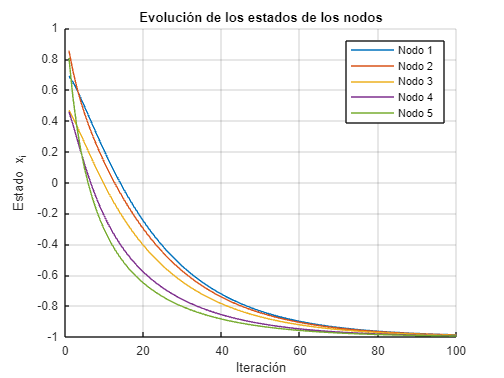


% Graficar la evolución de los estados de los nodos
figure;
hold on;
for i = 1:n
    plot(1:max_iter, x_a(i, :), 'DisplayName', ['Nodo ' num2str(i)]);
end
xlabel('Iteración');
ylabel('Estado x_i');
legend show;
title('Evolución de los estados de los nodos');
grid on;
hold off;

## **Restricción en los Estados de los Nodos**

Para analizar el impacto de restricciones en el consenso, se introduce un límite en los valores de los estados de los nodos, restringiéndolos al intervalo [−1,2]. Esta restricción evita que los valores de los nodos crezcan indefinidamente y permite estudiar cómo afecta la convergencia del sistema.

El método utilizado es el de consenso por vecinos directos, aplicando la restricción después de cada actualización de estado. De esta manera, cada nodo ajusta su estado considerando los valores de sus vecinos, pero si el nuevo estado calculado excede los límites establecidos, se trunca al valor máximo o mínimo permitido.

Se implementó una simulación para observar cómo esta restricción afecta la evolución de los estados de los nodos y la convergencia del consenso. Los resultados muestran que, si bien la restricción impide que los valores de los nodos se desvíen demasiado, también puede ralentizar la convergencia en comparación con el caso sin restriccione

% Parámetros iniciales
n = 5; % Número de nodos
alpha = 0.01; % Tasa de aprendizaje
max_iter = 100; % Número máximo de iteraciones
x = zeros(n, max_iter); % Inicializar estados de los nodos
x_b(:, 1) = rand(n, 1) * 3 - 1; % Valores iniciales aleatorios en [-1, 2]

% Matriz de adyacencia (grafo conexo)
A = [0 1 1 0 0;
     1 0 1 0 0;
     1 1 0 1 0;
     0 0 1 0 1;
     0 0 0 1 0];

% Normalizar la matriz de adyacencia para que sea doblemente estocástica
A = A ./ sum(A, 2);

% Algoritmo de consenso distribuido con restricción
for t = 1:max_iter-1
    for i = 1:n
        % Obtener los vecinos del nodo i
        neighbors = find(A(i, :) > 0);
        
        % Calcular el promedio ponderado de los estados de los vecinos
        weighted_sum = sum(A(i, neighbors) .* x_b(neighbors, t)');
        
        % Calcular el gradiente de la función de costo local
        gradient = 2*i + 2*i * x_b(i, t);
        
        % Actualizar el estado del nodo i
        x_b(i, t+1) = weighted_sum - alpha * gradient;
        
        % Proyectar el estado en el intervalo [-1, 2]
        x_b(i, t+1) = max(-1, min(2, x_b(i, t+1)));
    end
end

% Valor de consenso (estado final de los nodos)
consensus_value = mean(x_b(:, end)); % Promedio de los estados finales de todos los nodos
disp('El valor de consenso es:');

El valor de consenso es:


disp(consensus_value);

   -0.9970
   -0.9970
   -0.9969
   -0.9976
   -0.9971



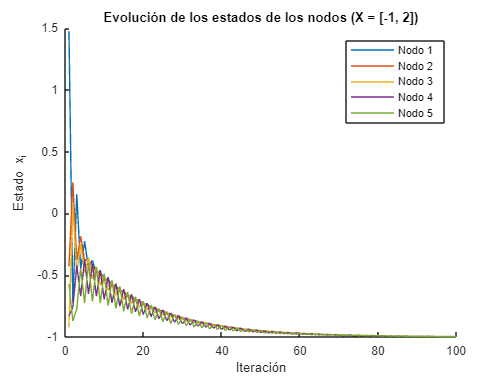


% Graficar 
figure;
hold on;
for i = 1:n
    plot(1:max_iter, x_b(i, :), 'DisplayName', ['Nodo ' num2str(i)]);
end
xlabel('Iteración');
ylabel('Estado x_i');
legend show;
title('Evolución de los estados de los nodos (X = [-1, 2])');
hold off;

% Matriz de adyacencia (grafo en la Figura 1)
A = [0 1 1 0 0;
     1 0 1 0 0;
     1 1 0 1 0;
     0 0 1 0 1;
     0 0 0 1 0];

% Normalizar la matriz de adyacencia para que sea doblemente estocástica
A = A ./ (sum(A, 2)); % Evita divisiones por cero

% Algoritmo de consenso distribuido
for t = 1:max_iter-1
    % Calcular la matriz de consenso W(t)
    D = diag(sum(A, 2)); % Matriz de grado
    L = D - A; % Matriz Laplaciana
    lambda = -1/n; % Parámetro de ajuste
    Wt = eye(n) + lambda * L; % Matriz de pesos doblemente estocástica
    
    % Calcular el gradiente de cada función de costo f_i(x) = 2i*x + i*x^2
    gradient = zeros(n, 1);
    for i = 1:n
        gradient(i) = (2 * i) + (2*i * x_b(i, t));
    end
    
    % Actualizar el estado de los nodos
    x_b(:, t+1) = Wt * x_b(:, t) - alpha * gradient;
end

% Valor de consenso (estado final de los nodos)
consensus_value = mean(x_b(:, end)); % Promedio de los estados finales
disp('El valor de consenso es:');

El valor de consenso es:


disp(consensus_value);

   -0.9931
   -0.9936
   -0.9946
   -0.9964
   -0.9972



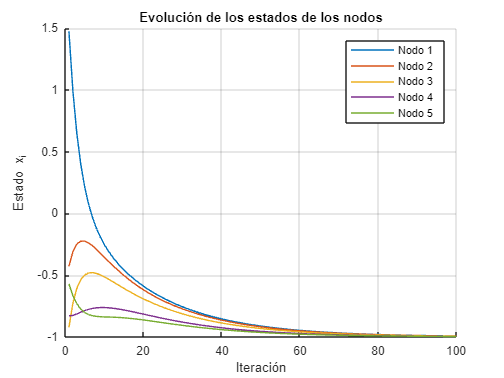


% Graficar la evolución de los estados de los nodos
figure;
hold on;
for i = 1:n
    plot(1:max_iter, x_b(i, :), 'DisplayName', ['Nodo ' num2str(i)]);
end
xlabel('Iteración');
ylabel('Estado x_i');
legend show;
title('Evolución de los estados de los nodos (X = [-1, 2])');
grid on;
hold off;

## **Consenso con Matriz de Adyacencia Variable**

Para evaluar el impacto de una red dinámica en el proceso de consenso, se introduce una variación en la estructura de la red en la que la matriz de adyacencia cambia aleatoriamente en cada iteración. Esto simula escenarios en los que las conexiones entre los nodos no son fijas, sino que pueden evolucionar con el tiempo debido a fallos en las conexiones, movilidad de los nodos o cambios en la topología de la red.

En este experimento, la matriz de adyacencia se actualiza de forma aleatoria dentro de ciertos límites para garantizar que la red permanezca conectada en la mayoría de los casos. Luego, se normaliza la matriz de adyacencia en cada iteración para mantener las propiedades necesarias para el cálculo del consenso.

Los resultados muestran que la convergencia del consenso puede verse afectada por la variabilidad en la red. En algunos casos, los cambios en la matriz de adyacencia ralentizan el proceso de consenso, mientras que en otros pueden acelerar la convergencia dependiendo de la estructura momentánea de la red. Esta variación introduce un nivel adicional de incertidumbre en el sistema y refleja la importancia de considerar la estabilidad de la topología de la red en aplicaciones del mundo real.

clc; clear; close all;

% Parámetros iniciales
n = 5; % Número de nodos
iterations = 300; % Número de iteraciones
alpha = 0.01; % Tasa de aprendizaje

% Matriz de adyacencia inicial (conectada)
A = [0 1 1 0 0;
     1 0 1 0 0;
     1 1 0 1 0;
     0 0 1 0 1;
     0 0 0 1 0];
 
% Estado inicial aleatorio entre -5 y 5 
x = zeros(n, iterations);
x(:,1) = rand(n, 1);

% Simulación de la evolución temporal con A(t) variable
for t = 2:iterations-1
    % Modificar aleatoriamente algunas conexiones en A(t) para simular variabilidad
    At = A;
    if rand < 0.5 % Probabilidad de cambio en la estructura
        i = randi(n);
        j = randi(n);
        if i ~= j
            At(i, j) = ~At(i, j);
            At(j, i) = At(i, j); % Mantener simetría
        end
    end
    
    % Calcular la matriz de consenso W(t)
    D = diag(sum(At, 2)); % Matriz de grado
    L = D - At; % Laplaciana
    lambda = -1/n; % Parámetro de ajuste
    Wt = eye(n) + lambda * L; % Matriz de pesos doblemente estocástica
    
    % Calcular el gradiente de cada función de costo f_i(x) = 2i*x + i*x^2
    gradient = zeros(n, 1);
    for i = 1:n
        gradient(i) = (2 * i) + (2*i * x(i, t));
    end
    
    % Aplicar la ecuación de consenso con descenso de gradiente
    x(:,t+1) = Wt * x(:, t) - alpha * gradient;
end
disp(x(iterations))

   -0.9755



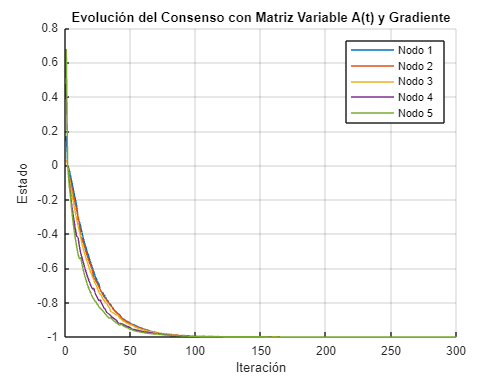

% Graficar la evolución del consenso
figure; hold on;
for i = 1:n
    plot(1:iterations, x(i, :), 'DisplayName', ['Nodo ', num2str(i)]);
end
hold off;
title('Evolución del Consenso con Matriz Variable A(t) y Gradiente');
xlabel('Iteración');
ylabel('Estado');
legend;
grid on;